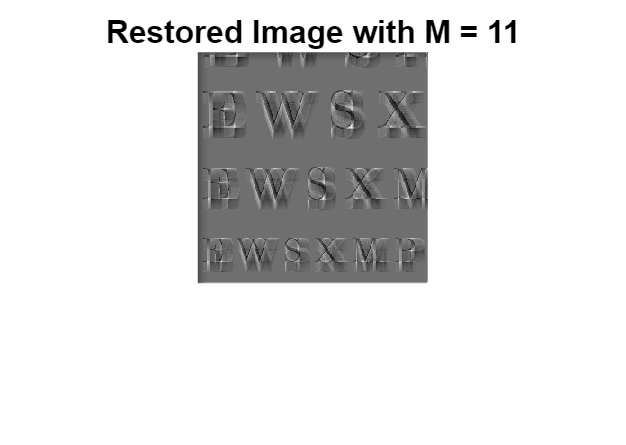

Worst-Case Error for M = 11: 600.8593


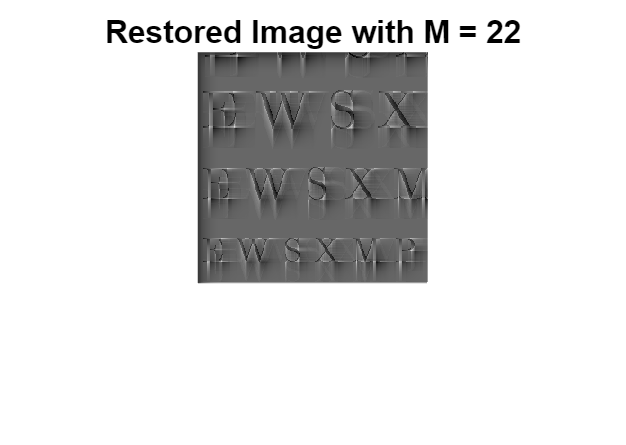

Worst-Case Error for M = 22: 686.9308


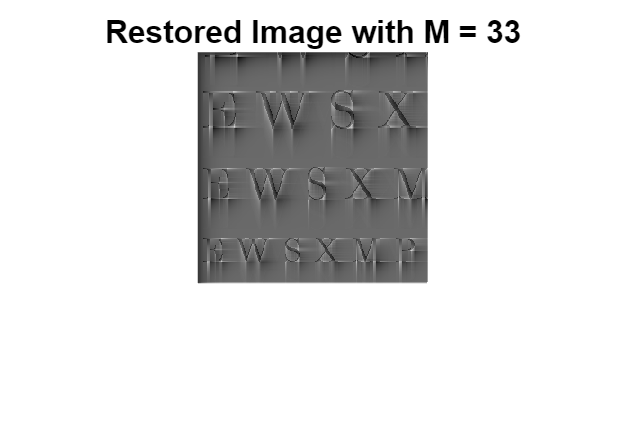

Worst-Case Error for M = 33: 709.7653


% Define FIR FILTER-1 coefficients
q = 0.9;
b1 = [1, -q];

% Define the filter lengths for FIR FILTER-2
M_values = [11, 22, 33];
r = 0.9;

% Preallocate for results
best_m = 0;
best_restored_image = [];
best_error = Inf;

for M = M_values
    % Define FIR FILTER-2 coefficients
    b2 = r.^(0:M);

    % Apply FIR FILTER-2 along the horizontal direction
    y_horizontal_filtered = filter(b2, 1, ech90, [], 2);

    % Apply FIR FILTER-2 along the vertical direction
    y = filter(b2, 1, y_horizontal_filtered, [], 1);

    % Display the restored image
    figure;
    imshow(y, []);
    title(['Restored Image with M = ', num2str(M)]);
    
    % Calculate the error
    error = echart - y;

    % Evaluate the worst-case error
    worst_case_error = max(abs(error(:)));
    disp(['Worst-Case Error for M = ', num2str(M), ': ', num2str(worst_case_error)]);
    
    % Find the best result
    if worst_case_error < best_error
        best_error = worst_case_error;
        best_m = M;
        best_restored_image = y;
    end
end

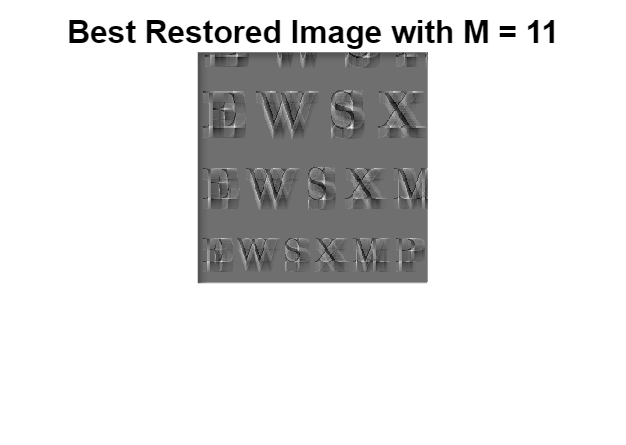


% Display the best restored image
figure;
imshow(best_restored_image, []);
title(['Best Restored Image with M = ', num2str(best_m)]);